% MANUALLY LOAD .mat FILES FOR INDIVIDUAL ANALYSIS

% CALC'S FOR LATER
RoundXpts = round(abs(yPickedPts)); %switch x & y
RoundYpts = round(abs(xPickedPts));


clear PTSdfof % pulling fluoresence data from just teh points picked in threshPassAnalysis script
for i = 1:length(xPickedPts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:);
end
display('size of PTSdfof is: ')
size(PTSdfof)


% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

conOrderedByTrial = con(trialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
uniqueContrasts = unique(con); % for looping over contrast values later


% DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

durOrderedByTrial = dur(trialCond); % save in new vector that is a list 
% of trial conditions ordered by trial

uniqueDurations = unique(dur); % for looping later


% common figure calc's

reigons = {'V1','LM','RL','PM','control'};
cons4Legend = {'0','0.03','0.063','0.125','0.25','0.5','1'};
durs4Legend = {'16','33','66','133','266'};

% CONTRAST FIGURES

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames

clear frameNum
frameNum = 1:size(onsetDf,3); % making the x axis frame number - 3rd dimension (frames) of onsetDf 

clear r
r = 1; % since I know the number of reigions is equal to the number of xpts, i'll just index regions
% w/in the xpts loop and add 1 to the index each time. the 'r' index should be equal to i at the end (could maybe just use i?)

clear subplotNum
subplotNum = 1;

figure % make one figure for all subplots
% set(t, 'FontSize', 8)
suptitle('df/f vs frames for each stimulus presentation, across visual areas')
clear i
for i = 1:length(xpts) % for each point
    
    subplot(2,3,i)% 
    plot(frameNum,squeeze(PTSdfof(i,:,:))) % plot dfof the first point vs frames for all trials 
    
%     if subplotNum == 1
%         ylabel('df/f')
%         xlabel ('frames')
%     else
%         set(gca,'XTick',[], 'YTick', [])
%     end

    hold on
    
    plot(mean(squeeze(PTSdfof(i,:,:)),2),'linewidth',4) 
    
    ylim([-0.225 0.225]) 
    xlim([0 51])
    
    st = title(sprintf('%s', reigonsTitle{r}));
   
    if subplotNum == 1
        
        ylabel('df/f')
        xlabel ('frames')
%     else
%         set(gca,'XTick',[], 'YTick', [])
    end
    
    r = r+1;
    subplotNum = subplotNum+1;
    
end
    
hold on % now plot the mean for each point on the 6th subplot
for j = 1:length(xpts)
    subplot(2,3,6)
    plot(mean(squeeze(PTSdfof(j,:,:)),2),'linewidth',1) % here's plotting the mean over trials (dimension 2 in PTSdfof)
    ylim([-0.02 0.02]) 
    xlim([0 51])
    % set(gca,'XTick',[], 'YTick', [])
    hold on
end
hold on
legend(reigons)

% MEAN DF/F vs FRAMES for each CONTRAST, per visual area
% mean TRACE = contrast, SUBPLOT = point

clear subplotNum
subplotNum = 1;
clear r
r = 1;

figure % only making 1 figure
suptitle(sprintf('df/f vs frames for each contrast in each visual area'))   

clear i
for i = 1:length(xPickedPts) % for each point
    subplot(2,3,i) % give each point it's own subplot
    % on each subplot plot the mean dfof across trials, vs frames
    
    % now on each subplot/for each point we're going 
    % to plot the mean across trials at each contrast, for each contrast
    clear c
    for c = 1:length(uniqueContrasts) 
        clear cthTrials
        %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
        % 1x51 variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frames
        
        %STDEV
        err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
        % stdOverTrialsPTSdfof = (std(meanOverTrialsPTSdfof)/sqrt(trials);
        % err = stdOverTrialsPTSdfof*ones(size(meanOverTrialsPTSdfof)); % b/c just one stdev for whole trace across trials at the c-th contrast
        
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
        clear x_axis
        x_axis = 1:length(meanOverTrialsPTSdfof);
        errorbar(x_axis,meanOverTrialsPTSdfof,err,'linewidth',1)
        
        ylim([-0.025 0.04]) 
        xlim([1 length(x_axis)])
        st = title(sprintf('%s', reigonsTitle{r}));

        
        %if subplotNum == 1
            ylabel('df/f')
            xlabel ('frames')
%         else
%             set(gca,'XTick',[], 'YTick', [])
%         end
        
        hold on
       
    end
    
   % if subplotNum == 1
        legend(contrastsTitle)
   % end
    
    subplotNum = subplotNum + 1;
    r = r+1;
    
end 
    
    % collect all the matricies for all the i-th points
%     sqForGroupMeanOverTrialsPTSdfof = squeeze(forGroupMeanOverTrialsPTSdfof);
%     allPtsMeanOverTrialsPTSdfof(:,:,i) = sqForGroupMeanOverTrialsPTSdfof;
    
% now for each contrast figure, I want the 6th subplot to be the
% average trace for each contrast, across visual areas
    
hold on

clear c
for c = 1:length(uniqueContrasts)
    
    subplot(2,3,6) 
        
    clear cthTrials
    %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
    cthTrials = conOrderedByTrial == uniqueContrasts(c); 
       
    clear allIthCthMeanSqPTSdfofCthTrials % this gets cleared out in between contrasts, not points
        
    clear i
    for i = 1:length(xPickedPts) 
            
        % collect mean df/f vs frames for each point at the c-th contrast
        allPtsAtCthConMeanSqPTSdfofCthTrials(i,:) = mean(squeeze(PTSdfof(i,:,cthTrials)),2)';
    
    end
    
    clear meanOverPts4CthConMeanSqPTSdfofCthTrials
    
    % take the mean across points of the matrix we just collected
    % this gives us one trace for all points at the cth contrast
    meanOverPts4CthConMeanSqPTSdfofCthTrials = mean(allPtsAtCthConMeanSqPTSdfofCthTrials,1);
   
    plot(meanOverPts4CthConMeanSqPTSdfofCthTrials,'linewidth',2) 
       
    hold on

end
    
ylim([-0.025 0.04])
xlim([1 length(x_axis)])
sst = title('mean per contrast')

sst =   Text (mean per contrast) with properties:

                 String: 'mean per contrast'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [12 0.040889 1.4211e-14]
                  Units: 'data'

  Show all properties


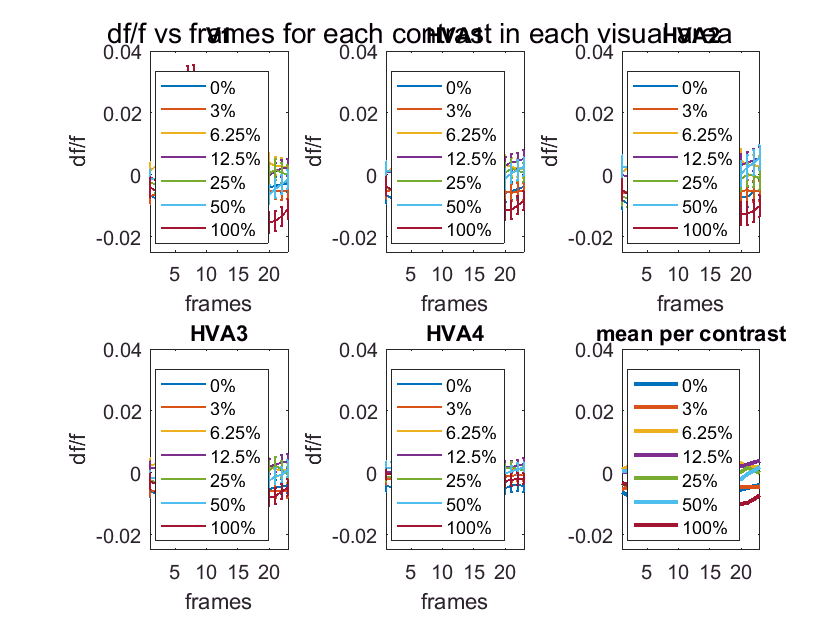

legend(contrastsTitle)

% LATENCY vs CONTRAST for each Vis Area
% find the max, and then the frame the max is at

% lets pick 
clear c
clear i

% 7 contrasts for x axis
x_axis = [1 2 3 4 5 6 7];

subplotNum = 1
r = 1

figure;
suptitle('Latency vs Contrast for each visual area')
for i = 1:length(xpts)
    
    clear maxContRespOverFramesTrialsPTSdfof % clear this so the mean dfof for each points dont write over each other, plotting nonsense
    clear contLatencyInFrames
    
    for c = 1:length(uniqueContrasts)
        
        clear meanOverTrialsPTSdfof
        clear maxOverFramesTrialsPTSdfof 
        clear latencyInFrames
        clear cthTrials
        
        cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthConOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        maxOverFramesTrialsPTSdfof = max(meanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        latencyInFrames = find(meanOverTrialsPTSdfof == maxOverFramesTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect cth latency values into a vector that should be the same length as maxContRespOverFramesTrialsPTSdfof 
        contLatencyInFrames(1,c) = latencyInFrames; % one row, each 7 columnns  
        
        % saving each cth latency value 
        contMaxOverFramesTrialsPTSdfof(1,c) = maxOverFramesTrialsPTSdfof;
        
        % STDEV
        % we only want the frames for the latencies for our max values, but still need stdev over trials
        %latTrials = latencyInFrames
        stdErrConLatOverTrials(1,c) = std(PTSdfof(i,latencyInFrames,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
    format short g
    convertFrames2Sec = 0.1*contLatencyInFrames;
    
    % for GROUP
    % collect all the latency for each contrast over all trials into a 2-D variable
    % with the cells as latency, 1st dimension as points (rows), the second dim as contrasts
    % the below is 5 x 7 
     %allPtsConvertFrames2Sec(i,:) = convertFrames2Sec;
     
    % still w/in the points for loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     % scatter(x_axis,convertFrames2Sec)
     errorbar(x_axis,convertFrames2Sec,stdErrConLatOverTrials,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     st = title(sprintf('%s', reigons{r}));
     ylim([0 6]) 
     xlim([0 8])
     
     if subplotNum == 1
        xlabel('contrasts plotted as log linear')
        ylabel('seconds')
        xt={'0' ; '0.03' ; '0.0625' ; '0.125' ; '0.25'; '0.5'; '1';} ; 
        set(gca,'xtick',1:7);
        set(gca,'xticklabel',xt);
    else
        set(gca,'XTick',[], 'YTick', [])
    end
    
subplotNum = subplotNum + 1;
r = r + 1;
     
end


% CRF w/ PEAK (MEAN @ LATENCY) --> determined by looking at latency.. just taking mean at these frames, not using max function
% CRF over frames 14-16

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 14:16;

subplotNum = 1;
r = 1;

figure 
suptitle('Contrast Response Functions for Each Point')
for i = 1:length(xpts)
    
    clear sq5FramesOverTrialsPTSdfof
    clear meanOverFramesSq5FramesOverTrialsPTSdfof
    clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contStdErr
    
    for c = 1:length(uniqueContrasts)
        
        clear cthTrials
        cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthConOrderedByTrialMeetCriteria == uniqueContrasts(c);  
        
        % CRF POINTS for each contrast, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthTrials));
        
        % take the mean over frames
        %returns 1 x 76 (trials)
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each c-th CRF value for this point
        % creates 1 x 7 (contrasts)
        contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
        contStdErr(1,c) = stdErr;
        
    end 
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1 2 3 4 5 6 7];
    crfChart = errorbar(x_axis,contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    st = title(sprintf('%s', reigons{r}));
    ylim([-0.02 0.05]) 
    xlim([0, 8])
    ylabel('df/f')
    xlabel('contrasts plotted as log linear')
    
    ax=crfChart.Parent;
    ax.XMinorTick = 'on'; %more tick marks
    set(ax, 'XTick', 0:1:8);
%     clear xt
%     xt={'0' ; '0.03' ; '0.0625' ; '0.125' ; '0.25'; '0.5'; '1';} ; 
%     set(gca,'xtick',1:7);
%     set(gca,'xticklabel',xt);
    
subplotNum = subplotNum+1;
r = r+1;
    
end 

%savefig('G6H277RT_020421_CRF_imThreshPass')

% DISTRIBUTION
% Now need to plot the distribution of amplitude values at t = 15, for each contrast and each point

clear r
r = 1;
clear subplotNum
subplotNum = 1;

pickFrame = 15; % based on latency plots

clear i
for i = 1:length(xpts) % for each point make a figure
    figure 
    %suptitle(sprintf('Frequency of Pixel Response Magnitudes for Each Contrast, ','%s', reigons{r}))
    t = suptitle(sprintf('Frequency of Pixel Response Magnitudes for Each Contrast, %s', reigons{r}));
    clear c
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
       
        clear cthConOrderedByTrialMeetCriteria
        clear cthTrials
        
        cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthConOrderedByTrialMeetCriteria == uniqueContrasts(c);
        sum(cthTrials);
       
        % taking the i-th point, frame 15, c-th trials & squeezing a singleton out
        % gives me dF/F for one point for all 15th frames at this contrast
        sqOneFrameOverTrialsPTSdfof = squeeze(PTSdfof(i,pickFrame,cthTrials))'; 
      
        % CANT do: store output vectors for each contrast
        % contSqOneFrameOverTrialsPTSdfof(:,:,c) = sqOneFrameOverTrialsPTSdfof; % 1x7, mean dfof (at frame 15) for each contrast
        % the problem here is that every vector 'sqOneFrame..' is a different length, so can't 'collect'
        % Better to just plot directly on the subplot here
        
        subplot(2,4,c) % make a subplot for each contrast
        
        %numBins = sum(cthTrials);
        numBins = 20;
        histChart = histogram(sqOneFrameOverTrialsPTSdfof,numBins);
        xlim([-0.2 0.2])
        ylim([0 40])
        
        ax=histChart.Parent;
        ax.XMinorTick = 'on'; %more tick marks
        set(ax, 'XTick', -0.2:0.1:2.0);
        
        if c == 1
            ylabel('number of trials')
            xlabel('df/f @ t = 1.5s')
        end
        
        st = title(sprintf('c = %s', cons4Legend{c}));
        
    end % we're still in the i loop
    
    hold on 
    
    clear contStdErr
    clear contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    
    clear c
    for c = 1:length(uniqueContrasts);
        
        clear cthTrials
        clear cthConOrderedByTrialMeetCriteria
        cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthConOrderedByTrialMeetCriteria == uniqueContrasts(c);  
        
        clear sq5FramesOverTrialsPTSdfof
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    
        % calculate *individual* CRF POINTS for cth contrast, i-th point:
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthTrials));
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
       
        % STDERR
        % I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
        contStdErr(1,c) = stdErr;
        
    end
    
     % 7 contrasts for x axis
     x_axis = [1 2 3 4 5 6 7];
     subplot(2,4,8)
     errorbar(x_axis,contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,contStdErr,'-s','MarkerSize',3,...
     'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     st = title(sprintf('CRF for reigon %s', reigons{r}));
     ylabel('df/f')
     xlabel('contrasts plotted as log linear')
     xlim([0 8])
     ylim([-0.02 0.05]) 
     
     % set(gca,'XTick',[], 'YTick', [])
%      xt={'0' ; '0.03' ; '0.0625' ; '0.125' ; '0.25'; '0.5'; '1';} ; 
%      set(gca,'xtick',1:7);
%      set(gca,'xticklabel',xt);
     
subplotNum = subplotNum+1;
r = r+1;
    
end
    
%savefig('G6H277RT_020421_ConHisto')
